% number of particles: n
n = 10

n = 10



% Define:
% For each particles, to calculate the Electromagnetic force, we need:
% charge: q
% velocity: v
% position: x
% Define in matrix form
% P 1xN
Q = [
    1;
    -1;
    -2;
    -3;
    -4;
    5;
    3.5;
    1;
    2;
    -2
    ];
Q = Q * 1e-9;
%V 3xN
%V = []
V = zeros(n,3);
%X 3xN
%X = []
X = rand(n,3,'double');

% Define Constants:
% 1. Coulomb constant(ke): electrostatic constant
e0 = 8.8541878128e-12

e0 = 8.8542e-12

ke = 1 / (4*pi*e0) 

ke = 8.9876e+09

% 2. magnetic constant(u0): magnetic constant
%u0 = 1.25663706e-6
km = 1e-7

km = 1.0000e-07

% field visualisation:
cx = 0:0.05:1;
cy = 0:0.05:1;
cz = 0:0.05:1;
[CX,CY,CZ] = meshgrid(cx,cy,cz);

for i = cx
    for j = cy
        for k = cz

            for index = 1:10
                  
            end

        end
    end
end




%init array for electromagnetic force
% this is the moving case
F_EM = zeros(n,3);
Electrostatic = zeros(n,3);
Magnetic = zeros(n,3);

for i = 1:n
    for j=1:n
        if i~=j 
            d = norm(X(i,:)-X(j,:));
            r = (X(j,:)-X(i,:))/d;
            Electrofield = Q(j) * ke / (d*d) * r;
            Magfield = Q(j) * km / (d*d) * (cross(V(j,:),r));
            Electrostatic(i,:) = Electrofield;
            Magnetic(i,:) = Magfield;
            F_EM(i,:) = F_EM(i,:) + Q(i)*(Electrofield + Magfield);
        end
    end
end
   

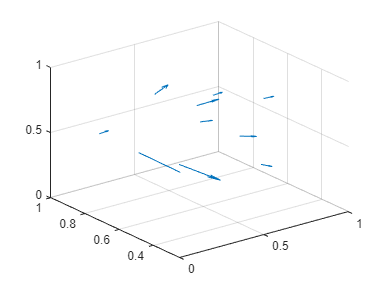

quiver3(X(:,1),X(:,2),X(:,3),Electrostatic(:,1),Electrostatic(:,2),Electrostatic(:,3));